clc
clear

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);

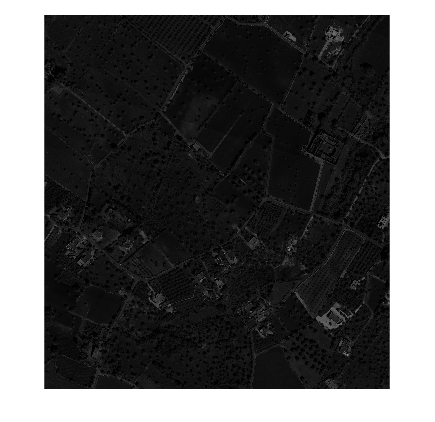

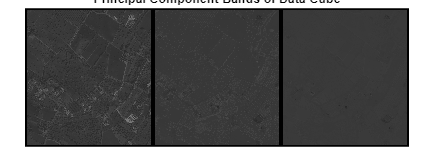

% Calculating PCA
[image,components] = PCA(hcube,3);

% k-means clustering
num_clusters = 6;

% Reshaping image
pixels = reshape(image, [], size(image, 3));

opts = statset('Display','final','MaxIter',10000);
[idx, centers] = kmeans(pixels, num_clusters, 'Options', opts);

Replicate 1, 71 iterations, total sum of distances = 40996.4.


Best total sum of distances = 40992.6


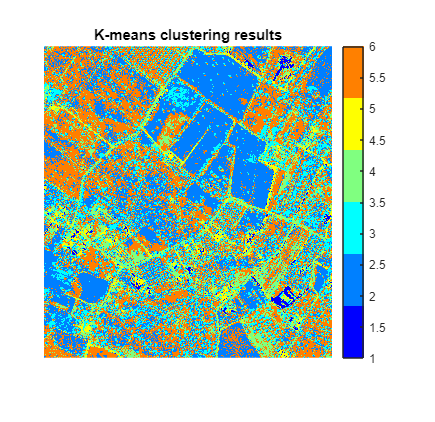


% Obtaining image's sizes
[rows, cols, ~] = size(image);

% Plot results
figure;
imshow(reshape(idx, [rows, cols]), []);
colormap(jet(num_clusters));
colorbar;
title('K-means clustering results');